## EBS 221 Agricultural Robotics

## Spring Quarter 2025

### **Assignment 1**

#### Please submit a single assignment file (either PDF or Word) along with all necessary Matlab files to reproduce the results. This is a group assignment, so each team will submit one report (including the source code). The grade will also be the same for all team members. 

#### **A. **(60 pts) Implement the bicycle model with 1st -order closed-loop steering and speed dynamics in a MATLAB function called robot_bike_dyn(). Use global variables for dt, DT (case-sensitive).

    function q_next = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, tau_gamma, tau_v)

    global dt; global DT;

    model of a vehicle with closed-loop steering and velocity control

    the combined effect of steering/vehicle inertia and control is a first order system for steering     (tau_gamma) and velocity (tau_v) state is vector q 

    % q(1) -> x

    % q(2) -> y

    % q(3) -> theta (orientation in world frame) 

    % q(4) -> gamma (steering angle)

    % q(5) -> v (linear velocity)

    % inputs are: % u(1) -> desired steering angle (gamma_d) % u(2) -> desired linear velocity (v_d) 

function q_next = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, tau_gamma, tau_v)
    global dt; global DT;

    % Unpack state vector
    x     = q(1);
    y     = q(2);
    theta = q(3);
    v     = q(4);
    gamma = q(5);

    % Unpack and saturate input
    gamma_d = max(min(u(1), umax(1)), umin(1));  % desired steering angle
    v_d     = max(min(u(2), umax(2)), umin(2));  % desired speed

    % Compute derivatives based on model
    dx     = v * cos(theta);
    dy     = v * sin(theta);
    dtheta = v * tan(gamma) / L;
    dv     = (-v + v_d) / tau_v;
    dgamma = (-gamma + gamma_d) / tau_gamma;

    % Euler integration to update state
    x     = x + dt * dx;
    y     = y + dt * dy;
    theta = theta + dt * dtheta;
    v     = v + dt * dv;
    gamma = gamma + dt * dgamma;

    % Saturate updated state
    x     = max(min(x, Qmax(1)), Qmin(1));
    y     = max(min(y, Qmax(2)), Qmin(2));
    theta = max(min(theta, Qmax(3)), Qmin(3));
    v     = max(min(v, Qmax(4)), Qmin(4));
    gamma = max(min(gamma, Qmax(5)), Qmin(5));

    % Pack next state
    q_next = [x; y; theta; v; gamma];
end

% Set global timestep
global dt DT;
dt = 0.1;     % integration time step
DT = 0.1;     % not used in current code, but declared

% Initial state: [x; y; theta; v; gamma]
q = [0; 0; 0; 0; 0];

% Desired inputs: [gamma_d; v_d]
u = [0.2; 1.0];  % 0.2 rad steering, 1 m/s velocity

% Input limits: [gamma_min, v_min], [gamma_max, v_max]
umin = [-0.5; 0];
umax = [0.5; 5.0];

% State limits: [x, y, theta, v, gamma]
Qmin = [-Inf; -Inf; -pi; 0; -0.5];
Qmax = [ Inf;  Inf;  pi; 2;  0.5];

% Vehicle parameters
L = 2.5;              % wheelbase in meters
tau_gamma = 0.5;      % steering response time (s)
tau_v = 0.8;          % velocity response time (s)

% Call the function
q_next = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, tau_gamma, tau_v);

% Display next state
disp('Next state:');

Next state:


disp(q_next);

         0
         0
         0
    0.1250
    0.0400



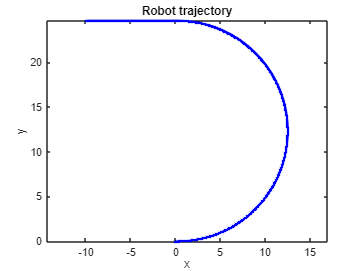

%%
N = 500;
Q = zeros(5, N);
Q(:,1) = q;

for k = 2:N
    Q(:,k) = robot_bike_dyn(Q(:,k-1), u, umin, umax, Qmin, Qmax, L, tau_gamma, tau_v);
end

% Plot trajectory
plot(Q(1,:), Q(2,:), 'b.-');
xlabel('x'); ylabel('y'); title('Robot trajectory');
axis equal;